## **Partial derivatives Introduction**

**Finding Partial Derivatives.**

clear vars
syms x y z
f= x^3 + y^3 +3*x*y*z+3*x*y*z^2 + 3*x^2*z + 3*x*y^2*z;
fx=diff(f,x)

$$fx = 3\,x^{2}+6\,x\,z+3\,y^{2}\,z+3\,y\,z^{2}+3\,y\,z$$

fy=diff(f,y)

$$fy = 3\,y^{2}+6\,x\,y\,z+3\,x\,z^{2}+3\,x\,z$$

fxx=diff(f,x,2)

$$fxx = 6\,x+6\,z$$

fyy=diff(f, y, 2)

$$fyy = 6\,y+6\,x\,z$$

fxy=diff(fx,y)

$$fxy = 3\,z+6\,y\,z+3\,z^{2}$$

fyx=diff(fy,x)

$$fyx = 3\,z+6\,y\,z+3\,z^{2}$$

**To find Level Curves**

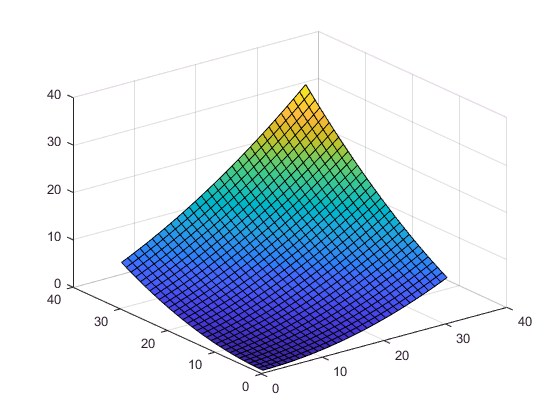

[X,Y]= meshgrid(0:0.1:3, 0:0.1:3);
z = (X+Y).^2;
surf(z)

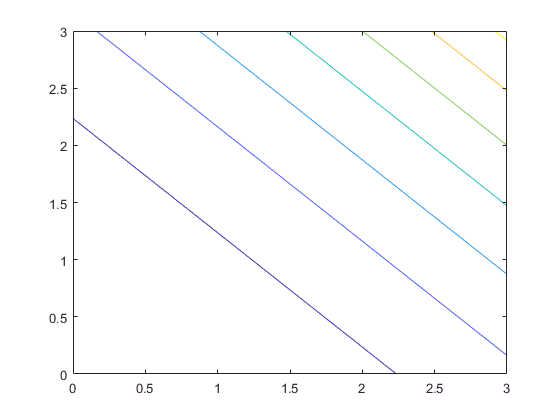

%level curves
contour(X,Y,z)

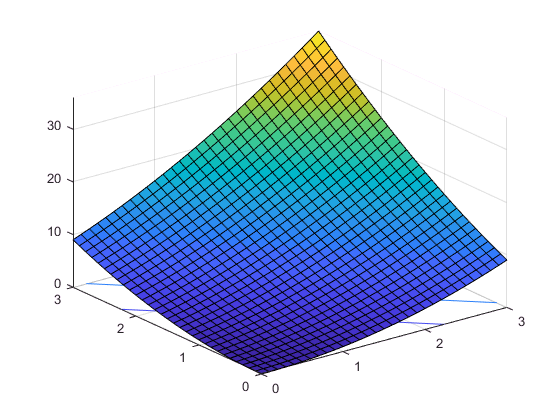

%level curves with surface
surfc(X, Y, z)

## MAXIMA AND MINIMA:

## Ex-1: Find the local maximum and minimum values of $f\left(x,y\right)=x^3 +3{\mathrm{xy}}^2 -15x^2 -15y^2 +72x$

clear vars
syms x y z
f=x^3+3*x*y^2-15*x^2-15*y^2+72*x

$$f = x^{3}-15\,x^{2}+3\,x\,y^{2}+72\,x-15\,y^{2}$$

fx=diff(f,x)

$$fx = 3\,x^{2}-30\,x+3\,y^{2}+72$$

fy=diff(f,y)

$$fy = 6\,x\,y-30\,y$$

[xc,yc]=solve(fx,fy,x,y,'real',true)

$$xc = \left(\begin{array}{c} 4\\ 6\\ 5\\ 5 \end{array}\right)$$

$$yc = \left(\begin{array}{c} 0\\ 0\\ -1\\ 1 \end{array}\right)$$

r=diff(fx,x)       % r = fxx

$$r = 6\,x-30$$

t=diff(fy,y)       % t = fyy

$$t = 6\,x-30$$

s=diff(fx,y)       % s = fxy

$$s = 6\,y$$

n=length(xc);

for i=1:n
    r1=subs(r,{x,y},{xc(i),yc(i)});   % fxx(xc,yc)
    s1=subs(s,{x,y},{xc(i),yc(i)});   %fxy(xc,y
    D=r*t-s^2;
    r2=subs(D,{x,y},{xc(i),yc(i)});
    if (r2>0) && (r1<0)
        fprintf("Local maximum exists at (%.2f, %.2f)\n",xc(i),yc(i))
        max_val=subs(f,{x,y},{xc(i),yc(i)});
        fprintf(" Local maximum value is %.2f\n",max_val)
    elseif (r2>0) && (r1>0)
        fprintf("Local minimum exists at (%.2f, %.2f)\n",xc(i),yc(i))
        min_val=subs(f,{x,y},{xc(i),yc(i)});
        fprintf(" Local minimum value is %.2f\n",min_val)
    elseif (r2< 0)
        fprintf("Saddle point exists at (%.2f, %.2f)\n",xc(i),yc(i))
    else
        dispaly('No conclusion about maxima or minima at this cirital point')
        end
end

Local maximum exists at (4.00, 0.00)


 Local maximum value is 112.00


Local mainimum exists at (6.00, 0.00)


 Local minimum value is 108.00


Saddle point exists at (5.00, -1.00)


Saddle point exists at (5.00, 1.00)


**LAGRANGE'S METOD:**

**Ex-2: A rectangular box without a lid is to be made from 12 **$m^2$** of cardboard. Find the maximum volume of such a box using Lagrange's method**

**Solution: Let the length, width, and height of the box (in meters) be x, y, and z as shown in Figure**

 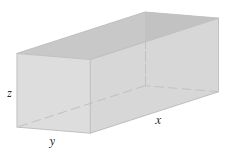

Volume of the box is V=xyz.

The area of the four sides and the bottom of the box is 2xz+2yz+xy =12.

syms x y z lambda
f=x*y*z    % Volume of the box

$$f = x\,y\,z$$

g=2*x*z+2*y*z+x*y-12     % constraint:  surface area of the box without lid

$$g = x\,y+2\,x\,z+2\,y\,z-12$$

ae=f+lambda*g            % auxillary equation

$$ae = \lambda \,\left(x\,y+2\,x\,z+2\,y\,z-12\right)+x\,y\,z$$

dae_x=diff(ae,x)

$$dae\_x = y\,z+\lambda \,\left(y+2\,z\right)$$

dae_y=diff(ae,y)

$$dae\_y = x\,z+\lambda \,\left(x+2\,z\right)$$

dae_z=diff(ae,z)

$$dae\_z = x\,y+\lambda \,\left(2\,x+2\,y\right)$$

L1=solve(dae_x,lambda)

$$L1 = -\frac{y\,z}{y+2\,z}$$

L2=solve(dae_y,lambda)

$$L2 = -\frac{x\,z}{x+2\,z}$$

L3=solve(dae_z,lambda)

$$L3 = -\frac{x\,y}{2\,x+2\,y}$$

eqns = [L1-L2 == 0, L1-L3 == 0];
%vars = [x y];
[solx, soly] = solve(eqns, x,y)

$$solx = 2\,z$$

$$soly = 2\,z$$

g1=subs(g,{x,y},{solx,soly})

$$g1 = 12\,z^{2}-12$$

z1=solve(g1,z>0)          %  z=z1

$$z1 = 1$$

x1=subs(solx,{z},{z1})    %  x=x1

$$x1 = 2$$

y1=subs(soly,{z},{z1})    %  y=y1

$$y1 = 2$$

max_vol=subs(f,{x,y,z},{x1,y1,z1})

$$max\_vol = 4$$

fprintf(" Maximum Volume of the box is %.2f cubic units",max_vol)

 Maximum Volume of the box is 4.00 cubic units

## Ex-3: Find the dimensions of the rectangular box with largest volume if the total surface area is 64${\mathrm{cm}}^{2\;}$using Lagrange's method.

syms x y z lambda
f=x*y*z    % Volume of the box

$$f = x\,y\,z$$

g=x*y+y*z+x*z-32     % constraint:  surface area of the box 

$$g = x\,y+x\,z+y\,z-32$$

ae=f+lambda*g            % auxillary equation

$$ae = \lambda \,\left(x\,y+x\,z+y\,z-32\right)+x\,y\,z$$

dae_x=diff(ae,x)

$$dae\_x = \lambda \,\left(y+z\right)+y\,z$$

dae_y=diff(ae,y)

$$dae\_y = \lambda \,\left(x+z\right)+x\,z$$

dae_z=diff(ae,z)

$$dae\_z = \lambda \,\left(x+y\right)+x\,y$$

L1=solve(dae_x,lambda)

$$L1 = -\frac{y\,z}{y+z}$$

L2=solve(dae_y,lambda)

$$L2 = -\frac{x\,z}{x+z}$$

L3=solve(dae_z,lambda)

$$L3 = -\frac{x\,y}{x+y}$$

eqns = [L1-L2 == 0, L1-L3 == 0];
%vars = [x y];
[solx, soly] = solve(eqns, x,y)

$$solx = z$$

$$soly = z$$

g1=subs(g,{x,y},{solx,soly})

$$g1 = 3\,z^{2}-32$$

z1=solve(g1,z>0)          %  z=z1

$$z1 = \frac{4\,\sqrt{6}}{3}$$

x1=subs(solx,{z},{z1})    %  x=x1

$$x1 = \frac{4\,\sqrt{6}}{3}$$

y1=subs(soly,{z},{z1})    %  y=y1

$$y1 = \frac{4\,\sqrt{6}}{3}$$

fprintf(" The dimensions of the rectangualr box are\n")

 The dimensions of the rectangualr box are


fprintf(" Length = %.2f, Width = %.2f and Height = %.2f\n",x1,y1,z1)

 Length = 3.27, Width = 3.27 and Height = 3.27
